# Airframe Model - 3DOF Projectile

## Topic

This LiveScript addresses the first part of your lesson on Airframes with the introduction of a three-degree-of-freedom projectile.

## Motivation

An important first step in the development of a model of UAV flight, is the development of the equations of motions.    In this module, beginning with simple Newtonian mechanics, you will review the governing laws of the physics of motion and the solution of the underlying differential equations for a small projectile flying through the air.   You will then develop a state-space formulation of the same problem that will be used as building block for the development of a more complicated model of UAV flight.

## Learning Objective

In this lesson you will go through the first steps of the development of a UAV airframe model.    You will begin with a quick review of the physics of motion and the numerical solution of the underlying differential equations. By the end of this first part of the airframe module, you will be able to:

- Write the equations of motion of a spherical mass in space, subject to gravity.

- Prepare and program closed-form solutions for these equations

## Lessons

### Utilities Used in Lesson

clear;
addpath('utils');

### Lesson A:  Projectile Model

It always helps to get an intuitive understanding of what you want to accomplish.  So to make things simple, you will begin with a simple projectile shooting game.   

In this game, you have the ability to shoot the spherical projectile.  You can control the aim of the projectile and the velocity of the projectile when you launch it.   After that, the projectile just flies according to the laws of physics and is accelerated by the force of gravity toward the ground.

**Input:  **

- Initial velocity:  $v_0$

- Angle from x-y plane: $\theta$

- Angle from x-axis:       $\phi$

**Output:**

- Graphical display of trajectory  (this is already programmed).  ( Note:  Try to hit the target!   There is more than one solution, try to find a few.)

**Task:**

The initial position of the mass is at the origin $\left(0,0,0\right)\ldotp \;\;$Try to hit the target by adjusting the initial angles $\left(\theta_0 \;,\phi_0 \right)$ and by making adjustments to the initial velocity $v_0$ and the interval of the flight $\left(0,t_{\max } \right)$.   

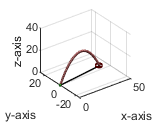

% Shooter

phi0    =   0.13;    % angle from -pi/2 to pi/2
theta0  = 1.1  ;       % angle from 0 to pi
v0      =  23;         % initial velocity (m/s)
tmax    =  5;         % duration of flight

projectileShooting(@fm,phi0,theta0,v0,tmax);

### Lesson B:   Equations of Motion 

The simple projectile in our motivational example flew in space and was only affected by the force of gravity.  Everything was easy to define in an inertial, "earth", reference frame.   The projectile was treated as a point mass and it only had three degrees of freedom.   Of course, a UAV is not a point mass and as you go through the modules, your models will develop to include many additional features, but since with each feature, everything gets more complex, this is a good place to start.  

#### Newton's Equations of Motion 

Newton's equations are vector valued, and in this simple case, each component is independent.  Therefore they can be written:

x-direction:   $0=m\frac{d^2 }{\mathrm{d}t^2 }x\left(t\right)$

y-direction:   $0=m\frac{d^2 }{\mathrm{d}t^2 }y\left(t\right)$

z-direction:    $-\textrm{mg}\;a_z =m\frac{d^2 }{\mathrm{d}t^2 }z\left(t\right)$

The solution can be found by integrating each of these equations twice and yields 


$$x\left(t\right)=x_0 +v_{x,0} \;t$$



$$y\left(t\right)=y_0 +v_{y,0} \;t$$



$$z\left(t\right)=z_0 +v_{z,0} \;t-\frac{1}{2}gt^2$$


At this point, you are almost done.    The only thing remaining is to specify the initial position

$\left(x_0 ,\;y_0 \;,\;z_0 \right)$ and compute the initial velocity vectors given the intial velocity $v_0$.

#### Computation of initial velocity vector

Defining the angles $\left(\phi \;,\;\theta \right)$ to be the angle from the (x-z) plane and from the (x,y) plane respectively, you get


$$v_{0,x} =v_0 \;\cos \left(\phi \right)\cos \left(\theta \right)$$



$$v_{0,y} =v_0 \;\sin \left(\phi \right)\cos \left(\theta \right)$$



$$v_{0,z} =v_0 \;\sin \left(\theta \right)$$


### Summary

Now you have everything you need.  The initial position and initial velocity of the projectile and the equations which characterize the flight path over time.

## Conclusion

The simple projectile in our motivational example flew in space and was only affected by the force of gravity.  Everything was easy to define in an inertial, "earth", reference frame.   The projectile was treated as a point mass and its motion could be described by three spatial coordinates x, y, and z.  It only had three degrees of freedom!   Of course, a UAV is not a point mass and as you go through the modules, your models will develop to include many additional features, but since with each feature, everything gets more complex, this was a good place to start.  

## Exercise:  Projectile Motion - Closed Form Solution

**Input:**

Newtonian equations of motion.

- Initial velocity:  $v_0$

- Angle from x-y plane: $\theta$

- Angle from x-axis:       $\phi$

- Time of flight simulation:  $t_{\max }$  

**Output:**

- MATLAB Subfunction that computes the flight of the projectile.

- Graphical display of trajectory.   (Note:  Have you recreated the simulation provided before?   Do the same solutions still work to hit the target?)

**Task:   Prepare a Subfunction**

Write a subfunction that given the input specified above, computes as output the coordinates of the flight path.    Use the space at the bottom of this script, replacing the constant input found there.  The code will be passed to a program below that creates the graphics.

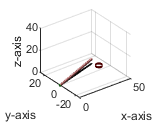

% Shooter

phid    =   0;    % angle from -90 degrees to +90 degrees
thetad  = 0  ;       % angle from 0 to 180 degrees
v0      =  25;         % initial velocity (m/s)
tmax    =  4;         % duration of flight

% You need to write the subfunction called myFlightModel with the inputs
% and outputs defined above.    Place the subfunction at the bottome of
% this LiveScript

% The function projectileShooting will take your function and plot the
% result
projectileShooting(@myFlightModel,phi0,theta0,v0,tmax);

**Subfunctions**

You should place your subfuctions below.   ** The subfunction myFlightModel ****needs to be replaced**** by one that you write!  **It should take the inputs for the angles, initial position, initiall velocity, and the length of the duration of flight, with the equations from this lesson, to model flight of a simple projectile under the influence of gravity.

function [t,X]=myFlightModel(phi, theta, z0, v0, tmax)
t=linspace(0,tmax,70);

%--------------------------------------
% Replace this code with your solution
x=10*t;   y=3*t;   z=t;
X=[x;y;z];
% --------------------------------------

end
